for i=1:11
    load(strcat('C294_d_',num2str(29+2*i),'_',num2str(31+2*i),'_t_',num2str(i),'.mat'));
    X(i)=sum(variable);
end
figure
plot(X);
for i=1:11
    %load(strcat('C294_testAlpha_v_',num2str(21+2*i),'_',num2str(23+2*i),'_t_',num2str(i),'.mat'));   
    %load(strcat('C294_v_',num2str(29+2*i),'_',num2str(31+2*i),'_t_',num2str(i),'.mat')); 
    %load(strcat('u0_030518B_psnrv_',num2str(28+2*i),'_',num2str(30+2*i),'_t_',num2str(i),'.mat')); 
    load(strcat('u0_C315_',num2str(28+2*i),'_',num2str(30+2*i),'_t_',num2str(i),'.mat')); 
    %X(i)=sum(abs(variable),'all');
    X4(i)=sum(abs(u),'all');
end
figure
plot(X4);
for i=1:11
    load(strcat('r0_C1191_',num2str(27+2*i),'_',num2str(29+2*i),'_t_',num2str(i),'.mat'));
    X(i)=sum(r);
end
figure
plot(X);

## interpolation error

TAG = ["WKY5";"WKY9";"WKY10"];
legends = [];
addpath('./Sensitivities', './analyzeFlows', genpath('./utilities'))
for ii=1:length(TAG)
    obj = Configuration3D(TAG(ii));
    obj.loadVolume;
    legends{ii} = sprintf("K=%d",obj.sigmaFunctionConstant);
    % PATH_TO_PYTHON = '/Users/Kaiming Xu/anaconda3/envs/rOMT';
    % [scalarMap, pathlines] = runPostprocessing(TAG, PATH_TO_PYTHON);
    % ms(5) = sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all');
    % figure
    % xaxis = ["0.00002","0.0002","0.002","0.02","0.2"];
    % plot(categorical(xaxis),ms)
    %disp('mean speed:');
    %disp(sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all'));
    ti = obj.timeInitial;
    tj = obj.timeJump;
    tf = obj.timeFinal;
    count = 0;
    for t1 = ti:tj:tf+tj
        count = count+1;
        if t1 == ti
            RHO{count} = readmatrix(sprintf('%s/rho_%s_%d_t_0.txt', ...
            obj.pathOutput, obj.tag, ti));
        else
            RHO{count} = importdata(sprintf('%s/%s_d_%d_%d_t_%d.mat', ...
            obj.pathOutput, obj.tag, ...
            t1 - tj, t1, (t1 - ti) ./ tj));
        end
    end
    
    % figure
    % xaxis = ["0.00002","0.0002","0.002","0.02","0.2"];
    % plot(categorical(xaxis),ms,'-o',categorical(xaxis),ie,'-o');
    % legend({'mean speed','interpolation error'},'fontsize',12);
    % xlabel("\sigma_0");
    % if ~isempty(obj.pathStartpointsMask)
    %     mask_brain = Mask(obj.pathStartpointsMask, obj.xRange,...
    %                 obj.yRange, obj.zRange, 1);
    %     if obj.do_resize
    %         mask_brain = mask_brain.resize(obj.sizeFactor);
    %     end
    % end
    % for i=1:11
    %     X(i) = norm(obj.Data(i).volume(:)-RHO{i});
    % end
    % figure
    % plot(X)
    % title('constant final time matching L2 error')
    %ie(5) = norm(obj.Data(11).volume(:)-RHO{11})/norm(obj.Data(11).volume(:));
    if ~isempty(obj.pathMask)
        csfMask = Mask(obj.pathMask, obj.xRange,...
                    obj.yRange, obj.zRange);
        if obj.do_resize
            csfMask = csfMask.resize(obj.sizeFactor);
        end
    end
    for i=1:length(obj.Data)
        A = reshape(obj.Data(i).volume(:),obj.trueSize);
        A(csfMask.contents == 0) = 0;
        B = reshape(RHO{i},obj.trueSize);
        B(csfMask.contents == 0) = 0;
        Xr1{ii}(i) = norm(A(:)-B(:))/norm(A(:));
        %X1{ii}(i) = norm(B(:));
        %Xg{ii}(i) = norm(A(:));
    end
end
    T=1:length(obj.Data);
    figure
    for ii = 1:length(TAG)
        hold on
        plot(T,Xr1{ii});
    end
    hold on
    legend(legends)
    title('interpolation error')
    
    %{
    figure
    legend("\alpha=350000,700000","ground truth")
    title('total density')
    %}



%{
figure
x = 1:11;
plot(x,XInf,x,X10,x,X100,x,X1000,x,X10000,x,X100000,x,X1000000)
legend({'original','K=10','K=100','K=1000','K=10000','K=100000','K=1000000'},'FontSize',15)
title("relative interpolation error")
set(gca,'FontSize',15)
%}

## plot density in mask

CAA12MonthTags = [ % 12 month rat brain
    "C282";
    "C293";
    "C294";
    "C295";
    "C298";
    "C313";
    "C315";
    "C316";
%    "C317";
    "C344";
%    "C347";
%    "C357";
    "C359";
    "C360";
    "C361";
    "C371";
    "C372";
    "C376"];
addpath('./Sensitivities', './analyzeFlows', genpath('./utilities'))
for ii = 10:length(CAA12MonthTags)
    obj = Configuration3D(CAA12MonthTags(ii));
    obj.plotVolume(obj.data_start,obj.data_end+1);
end

    obj = Configuration3D("C357");
    obj.plotVolume(24,obj.data_end+1);

## calculate property in csf region

PATH_TO_PYTHON = '/Users/Kaiming Xu/anaconda3/envs/rOMT';
CAATags = [ % CAA
    "C313";
    "C316";
    "C317";
    "C344";
    "C347";
    "C357";
    "C359";
    "C361";
    "C371";
    "C376"
    ];
WTTags = [
    "C282";
    "C293";
    "C294";
    "C295";
    "C298";
    "C315";
    "C360";
    "C372";
    ];
WKYTags = [
        "081618A_WKY_MCA_GLYMP";
    "081418A_WKY_MCA_GLYMP";

    "081718A_WKY_MCA_GLYMP";
    "081718B_WKY_MCA_GLYMP";
    ];
SHRSPTags = [
    "081418B_SHRSP_MCA_GLYMP";
    "081518A_SHRSP_MCA_GLYMP";
    "081518B_SHRSP_MCA_GLYMP";
    "081618B_SHRSP_MCA_GLYMP";
    ];
addpath('./Sensitivities', './analyzeFlows', genpath('./utilities'))
for ii = 1:length(WKYTags)
    obj = Configuration3D(WKYTags(ii));
    sigmalabels{ii} = sprintf("%d",obj.sigmaFunctionConstant);
    if ~isempty(obj.pathMask)
        csfMask = Mask(obj.pathMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange);
        if obj.do_resize
            csfMask = csfMask.resize(obj.sizeFactor);
        end
    end
    [scalarMap,~] = runPostprocessing(WKYTags(ii), PATH_TO_PYTHON);
    scalarMap.speed(csfMask.contents==0) = 0;
    scalarMap.flux(csfMask.contents==0) = 0;
    scalarMap.Pe(csfMask.contents==0) = 0;
    scalarMap.diffusionCoefficient(csfMask.contents==0) = 0;
    wkydCoeff(ii) = sum(scalarMap.diffusionCoefficient(scalarMap.diffusionCoefficient>0),'all')/sum(scalarMap.diffusionCoefficient>0,'all');
    wkySpeed(ii) = sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all');
    wkyFlux(ii) = sum(scalarMap.speed>0,'all');
    wkyPe(ii) = sum(scalarMap.Pe(scalarMap.Pe>0),'all')/sum(scalarMap.Pe>0,'all');
end

t = 1 (t1 = 15, t2 = 1 -> T = 15.000)
t = 2 (t1 = 15, t2 = 2 -> T = 15.200)
t = 3 (t1 = 15, t2 = 3 -> T = 15.400)
t = 4 (t1 = 15, t2 = 4 -> T = 15.600)
t = 5 (t1 = 15, t2 = 5 -> T = 15.800)
t = 6 (t1 = 15, t2 = 6 -> T = 16.000)
t = 7 (t1 = 15, t2 = 7 -> T = 16.200)
t = 8 (t1 = 15, t2 = 8 -> T = 16.400)
t = 9 (t1 = 15, t2 = 9 -> T = 16.600)
t = 10 (t1 = 15, t2 = 10 -> T = 16.800)
t = 11 (t1 = 17, t2 = 1 -> T = 17.000)
t = 12 (t1 = 17, t2 = 2 -> T = 17.200)
t = 13 (t1 = 17, t2 = 3 -> T = 17.400)
t = 14 (t1 = 17, t2 = 4 -> T = 17.600)
t = 15 (t1 = 17, t2 = 5 -> T = 17.800)
t = 16 (t1 = 17, t2 = 6 -> T = 18.000)
t = 17 (t1 = 17, t2 = 7 -> T = 18.200)
t = 18 (t1 = 17, t2 = 8 -> T = 18.400)
t = 19 (t1 = 17, t2 = 9 -> T = 18.600)
t = 20 (t1 = 17, t2 = 10 -> T = 18.800)
t = 21 (t1 = 19, t2 = 1 -> T = 19.000)
t = 22 (t1 = 19, t2 = 2 -> T = 19.200)
t = 23 (t1 = 19, t2 = 3 -> T = 19.400)
t = 24 (t1 = 19, t2 = 4 -> T = 19.600)
t = 25 (t1 = 19, t2 = 5 -> T = 19.800)
t = 26 (t1 = 19, t2 = 6 -> T = 2


for ii = 1:length(SHRSPTags)
    obj = Configuration3D(SHRSPTags(ii));
    sigmalabels{ii} = sprintf("%d",obj.sigmaFunctionConstant);
    if ~isempty(obj.pathMask)
        csfMask = Mask(obj.pathMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange);
        if obj.do_resize
            csfMask = csfMask.resize(obj.sizeFactor);
        end
    end
    [scalarMap,~] = runPostprocessing(SHRSPTags(ii), PATH_TO_PYTHON);
    scalarMap.speed(csfMask.contents==0) = 0;
    scalarMap.flux(csfMask.contents==0) = 0;
    scalarMap.Pe(csfMask.contents==0) = 0;
    scalarMap.diffusionCoefficient(csfMask.contents==0) = 0;
    shrspdCoeff(ii) = sum(scalarMap.diffusionCoefficient(scalarMap.diffusionCoefficient>0),'all')/sum(scalarMap.diffusionCoefficient>0,'all');
    shrspSpeed(ii) = sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all');
    shrspFlux(ii) = sum(scalarMap.speed>0,'all');
    shrspPe(ii) = sum(scalarMap.Pe(scalarMap.Pe>0),'all')/sum(scalarMap.Pe>0,'all');
end

t = 1 (t1 = 15, t2 = 1 -> T = 15.000)
t = 2 (t1 = 15, t2 = 2 -> T = 15.200)
t = 3 (t1 = 15, t2 = 3 -> T = 15.400)
t = 4 (t1 = 15, t2 = 4 -> T = 15.600)
t = 5 (t1 = 15, t2 = 5 -> T = 15.800)
t = 6 (t1 = 15, t2 = 6 -> T = 16.000)
t = 7 (t1 = 15, t2 = 7 -> T = 16.200)
t = 8 (t1 = 15, t2 = 8 -> T = 16.400)
t = 9 (t1 = 15, t2 = 9 -> T = 16.600)
t = 10 (t1 = 15, t2 = 10 -> T = 16.800)
t = 11 (t1 = 17, t2 = 1 -> T = 17.000)
t = 12 (t1 = 17, t2 = 2 -> T = 17.200)
t = 13 (t1 = 17, t2 = 3 -> T = 17.400)
t = 14 (t1 = 17, t2 = 4 -> T = 17.600)
t = 15 (t1 = 17, t2 = 5 -> T = 17.800)
t = 16 (t1 = 17, t2 = 6 -> T = 18.000)
t = 17 (t1 = 17, t2 = 7 -> T = 18.200)
t = 18 (t1 = 17, t2 = 8 -> T = 18.400)
t = 19 (t1 = 17, t2 = 9 -> T = 18.600)
t = 20 (t1 = 17, t2 = 10 -> T = 18.800)
t = 21 (t1 = 19, t2 = 1 -> T = 19.000)
t = 22 (t1 = 19, t2 = 2 -> T = 19.200)
t = 23 (t1 = 19, t2 = 3 -> T = 19.400)
t = 24 (t1 = 19, t2 = 4 -> T = 19.600)
t = 25 (t1 = 19, t2 = 5 -> T = 19.800)
t = 26 (t1 = 19, t2 = 6 -> T = 2

% figure
% plot(wkySpeed(1:3))
% xlabel('K')
% xticks([1, 2, 3])
% xticklabels(sigmalabels(1:3))
% title('mean speed')

for ii = 1:length(CAATags)
    obj = Configuration3D(CAATags(ii));
    if ~isempty(obj.pathStartpointsMask)
        csfMask = Mask(obj.pathStartpointsMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange, 2);
        if obj.do_resize
            csfMask = csfMask.resize(obj.sizeFactor);
        end
    end
    [scalarMap, ~,~] = runPostprocessing(CAATags(ii), PATH_TO_PYTHON);
    scalarMap.speed(csfMask.contents==0) = 0;
    scalarMap.flux(csfMask.contents==0) = 0;
    scalarMap.Pe(csfMask.contents==0) = 0;
    scalarMap.diffusionCoefficient(csfMask.contents==0) = 0;
    caadCoeff(ii) = sum(scalarMap.diffusionCoefficient(scalarMap.diffusionCoefficient>0),'all')/sum(scalarMap.diffusionCoefficient>0,'all');
    caaSpeed(ii) = sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all');
    caaFlux(ii) = sum(scalarMap.speed>0,'all');
    caaPe(ii) = sum(scalarMap.Pe(scalarMap.Pe>0),'all')/sum(scalarMap.Pe>0,'all');
end

for ii = 1:length(WTTags)
    obj = Configuration3D(WTTags(ii));
    if ~isempty(obj.pathStartpointsMask)
        csfMask = Mask(obj.pathStartpointsMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange, 2);
        if obj.do_resize
            csfMask = csfMask.resize(obj.sizeFactor);
        end
    end
    [scalarMap, ~,~] = runPostprocessing(WTTags(ii), PATH_TO_PYTHON);
    scalarMap.speed(csfMask.contents==0) = 0;
    scalarMap.flux(csfMask.contents==0) = 0;
    scalarMap.Pe(csfMask.contents==0) = 0;
    scalarMap.diffusionCoefficient(csfMask.contents==0) = 0;
    wtdCoeff(ii) = sum(scalarMap.diffusionCoefficient(scalarMap.diffusionCoefficient>0),'all')/sum(scalarMap.diffusionCoefficient>0,'all');
    wtSpeed(ii) = sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all');
    wtFlux(ii) = sum(scalarMap.speed>0,'all');
    wtPe(ii) = sum(scalarMap.Pe(scalarMap.Pe>0),'all')/sum(scalarMap.Pe>0,'all');
end

## calculate property in tissue region

PATH_TO_PYTHON = '/Users/Kaiming Xu/anaconda3/envs/rOMT';
CAATags = [ % CAA
    "C313";
    "C316";
    "C317";
    "C344";
    "C347";
    "C357";
    "C359";
    "C361";
    "C371";
    "C376"
    ];
WTTags = [
    "C282";
    "C293";
    "C294";
    "C295";
    "C298";
    "C315";
    "C360";
    "C372";
    ];
addpath('./Sensitivities', './analyzeFlows', genpath('./utilities'))
for ii = 1:length(CAATags)
    obj = Configuration3D(CAATags(ii));
    if ~isempty(obj.pathStartpointsMask)
        csfMask = Mask(obj.pathStartpointsMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange, 2);
        brainMask = Mask(obj.pathStartpointsMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange, 1);
        if obj.do_resize
            csfMask = csfMask.resize(obj.sizeFactor);
            brainMask = brainMask.resize(obj.sizeFactor);
        end
    end
    tissueMask = brainMask.contents - csfMask.contents;
    [scalarMap, pathlines] = runPostprocessing(CAATags(ii), PATH_TO_PYTHON);
    scalarMap.speed(tissueMask==0) = 0;
    scalarMap.flux(tissueMask==0) = 0;
    scalarMap.Pe(tissueMask==0) = 0;
    scalarMap.diffusionCoefficient(tissueMask==0) = 0;
    caadCoeff(ii) = sum(scalarMap.diffusionCoefficient(scalarMap.diffusionCoefficient>0),'all')/sum(scalarMap.diffusionCoefficient>0,'all');
    caaSpeed(ii) = sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all');
    caaFlux(ii) = sum(scalarMap.speed>0,'all');
    caaPe(ii) = sum(scalarMap.Pe(scalarMap.Pe>0),'all')/sum(scalarMap.Pe>0,'all');
end

for ii = 1:length(WTTags)
    obj = Configuration3D(WTTags(ii));
    if ~isempty(obj.pathStartpointsMask)
        csfMask = Mask(obj.pathStartpointsMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange, 2);
        brainMask = Mask(obj.pathStartpointsMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange, 1);
        if obj.do_resize
            csfMask = csfMask.resize(obj.sizeFactor);
            brainMask = brainMask.resize(obj.sizeFactor);
        end
    end
    tissueMask = brainMask.contents - csfMask.contents;
    [scalarMap, pathlines] = runPostprocessing(WTTags(ii), PATH_TO_PYTHON);
    scalarMap.speed(tissueMask==0) = 0;
    scalarMap.flux(tissueMask==0) = 0;
    scalarMap.Pe(tissueMask==0) = 0;
    scalarMap.diffusionCoefficient(tissueMask==0) = 0;
    wtdCoeff(ii) = sum(scalarMap.diffusionCoefficient(scalarMap.diffusionCoefficient>0),'all')/sum(scalarMap.diffusionCoefficient>0,'all');
    wtSpeed(ii) = sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all');
    wtFlux(ii) = sum(scalarMap.speed>0,'all');
    wtPe(ii) = sum(scalarMap.Pe(scalarMap.Pe>0),'all')/sum(scalarMap.Pe>0,'all');
end

## speed statistical

%% caa/wt
% speed = [caaSpeed',wtSpeed'];
% g = [ones(size(caaSpeed'))  2*ones(size(wtSpeed'))];
% typeOrder = ["CAA","WT"];
% namedTypes = categorical(g,1:2,typeOrder);
% [h,pValue] = ttest2(caaSpeed,wtSpeed);
% txt = strcat('p = ',num2str(pValue));
% figure
% boxchart(namedTypes,speed,'MarkerStyle','none');
% hold on
% swarmchart(g,speed,[],'red')
% ylim([0,0.25])
% title(txt)

## shrsp/wky

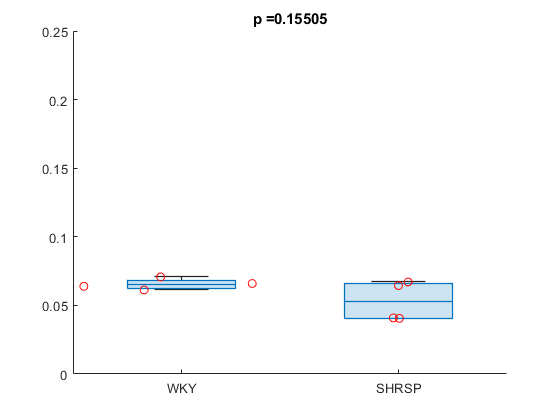

speed = [wkySpeed',shrspSpeed'];
g = [ones(size(wkySpeed'))  2*ones(size(shrspSpeed'))];
typeOrder = ["WKY","SHRSP"];
namedTypes = categorical(g,1:2,typeOrder);
[h,pValue] = ttest2(wkySpeed,shrspSpeed);
txt = strcat('p = ',num2str(pValue));
figure
boxchart(namedTypes,speed,'MarkerStyle','none');
hold on
swarmchart(g,speed,[],'red')
ylim([0,0.25])
title(txt)

## flux statistical

flux = [caaFlux',wtFlux'];
g = [ones(size(caaFlux'))  2*ones(size(wtFlux'))];
typeOrder = ["CAA","WT"];
namedTypes = categorical(g,1:2,typeOrder);
[h,pValue] = ttest2(caaFlux,wtFlux);
txt = strcat('p = ',num2str(pValue));
figure
boxchart(namedTypes,flux,'MarkerStyle','none');
hold on
swarmchart(g,flux,[],'red')
ylim([0,inf])
title(txt)

## pe statistical

pe = [caaPe',wtPe'];

Unrecognized function or variable 'caaPe'.

g = [ones(size(caaPe'))  2*ones(size(wtPe'))];
typeOrder = ["CAA","WT"];
namedTypes = categorical(g,1:2,typeOrder);
[h,pValue] = ttest2(caaPe,wtPe);
txt = strcat('p = ',num2str(pValue));
figure
boxchart(namedTypes,pe,'MarkerStyle','none');
hold on
swarmchart(g,pe,[],'red')
ylim([0,inf])
title(txt)

## WKY/SHRSP

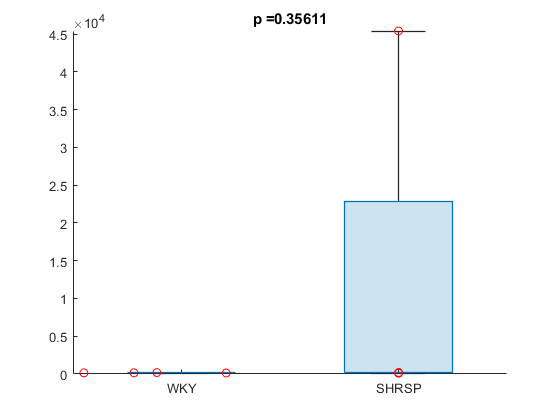

pe = [wkyPe',shrspPe'];
g = [ones(size(wkyPe'))  2*ones(size(shrspPe'))];
typeOrder = ["WKY","SHRSP"];
namedTypes = categorical(g,1:2,typeOrder);
[h,pValue] = ttest2(wkyPe,shrspPe);
txt = strcat('p = ',num2str(pValue));
figure
boxchart(namedTypes,pe,'MarkerStyle','none');
hold on
swarmchart(g,pe,[],'red')
ylim([0,inf])
title(txt)

## dCoeff statistical

dc = [caadCoeff',wtdCoeff'];
g = [ones(size(caadCoeff'))  2*ones(size(wtdCoeff'))];
typeOrder = ["CAA","WT"];
namedTypes = categorical(g,1:2,typeOrder);
[h,pValue] = ttest2(caadCoeff,wtdCoeff);
txt = strcat('p = ',num2str(pValue));
figure
boxchart(namedTypes,dc,'MarkerStyle','none');
hold on
swarmchart(g,dc,[],'red')
ylim([0,inf])
title(txt)


## dCoeff plot

x = 1:200;
X1 = 0.002 + 0*x;
X2 = 0.02./(1+x.^2/(10)^2);
X3 = 0.02./(1+x.^2/(100)^2)
figure
plot(x,X1,x,X2,x,X3)
ylim([0 0.03])
xlabel('|\nabla\rho|')
ylabel('\sigma')
legend('constant 0.002','anisotropic 0.02/(1+(x/10)^2)','anisotropic 0.02/(1+(x/100)^2)')
title('diffusion coefficient \sigma')